# TPA 1 Grupo 10

A continuación se resuelve el trabajo de aplicación 1.

## Inciso 1

El rango admisible de la entrada/salida es de 5V.

## Inciso 2

Se hizo un código en c que permite generar una señal de PWM con ciclo de trabajo variable.

Con esta señal de entrada, se ingresó primero al 20% durante

clear;
close all;
s = tf('s');

TIME_DIFF = 1e-3;


## Se cargan los datos

% addpath('c:\Users\tomi\Github\facu3\Control 3\TPA\1');
% savepath;
data = open('prot_sim_data.dat');

## Se grafican los datos de la simulacion

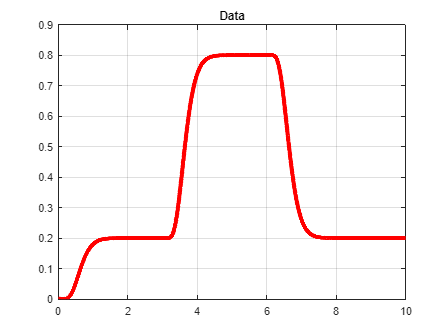

time = data.data(:,1);
y6 = data.data(:,7)/5; % se normaliza con respecto a 5V

figure();
plot(time, y6, 'r', 'linewidth', 4);
hold on;
grid on;
title('Data');

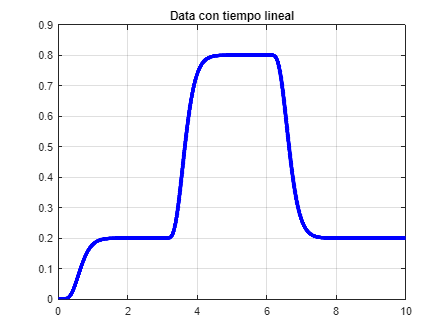


lineal_time = 0:TIME_DIFF:10;
lineal_y6 = interp1(time, y6, lineal_time);

figure;
plot(lineal_time, lineal_y6, 'b', 'linewidth', 4);
hold on;
grid on;
title('Data con tiempo lineal');

## Modelo FOPDT

step_resp = lineal_y6((3/TIME_DIFF):(5/TIME_DIFF));
step_resp=step_resp-0.2; % muevo los datos 0.2 porque se comenzó con 20% de duty cycle
step_resp=step_resp/0.6; % escalo a que la referencia sea 1, porque se puso 80% de duty cycle como step
step_time = lineal_time(1:length(step_resp));
step_input = ones(1, length(step_resp));
for i=1:length(step_resp)
    step_input(i) = step_time(i) > 0.0753;
end

close all;
fig = figure;
set(fig, 'Toolbar', 'none', 'Menu', 'none');
plot(step_time, step_resp, 'b', 'linewidth', 6);
hold on;
grid on;
title('Respuesta al escalón (de 20% a 80% ciclo de trabajo)');
xlabel('Tiempo [Segundos]');
ylabel('Tensión normalizada (a 5V) [Volts]');
plot(step_time, step_input, '--r', 'linewidth', 2);

% De los graficos generados se estima el delay
fopdt_delay = 0.415;
% De System Identification se obtuvieron los siguientes parámetros
fopdt_time_constant = 0.28562;
fopdt_gain = 1;

% Modelo FOPDT resultante
fopdt_estimated = fopdt_gain/(s*fopdt_time_constant+1);
fopdt_estimated.inputDelay = fopdt_delay;

[fopdt_est_y, fopdt_est_t] = step(fopdt_estimated, step_time); fopdt_est_y=reshape(fopdt_est_y, size(step_resp));
plot(fopdt_est_t, fopdt_est_y, 'k', 'linewidth', 2);
error_fopdt = immse(step_resp, fopdt_est_y);
fprintf('El error cuadrático medio entre la estimada y los datos es: %f\n', error_fopdt);

El error cuadrático medio entre la estimada y los datos es: 0.001009


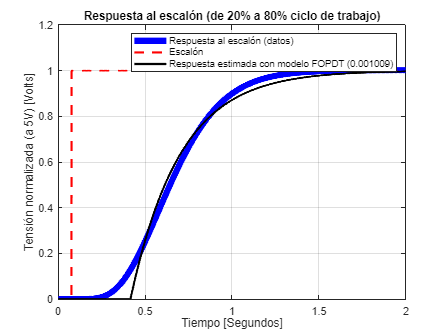

legend('Respuesta al escalón (datos)', 'Escalón', sprintf('Respuesta estimada con modelo FOPDT (%f)', error_fopdt), sprintf('Respuesta estimada con modelo SOPDT (%f)', error_sopdt));

## Modelo SOPDT

% Parámetros obtenidos de System Identification
sopdt_delay = 0.3272;
sopdt_time_constant_1 = 0.1798;
sopdt_time_constant_2 = 5;
sopdt_gain = 1;

% Modelo FOPDT resultante
sopdt_estimated = sopdt_gain/((s*sopdt_time_constant_1+1)*(s*sopdt_time_constant_1+1));
sopdt_estimated.inputDelay = sopdt_delay;

[sopdt_est_y, sopdt_est_t] = step(sopdt_estimated, step_time); sopdt_est_y=reshape(sopdt_est_y, size(step_resp));
plot(sopdt_est_t, sopdt_est_y, 'm', 'linewidth', 2);

error_sopdt = immse(step_resp, sopdt_est_y);
fprintf('El error cuadrático medio (SOPDT) entre la estimada y los datos es: %f\n', error_sopdt);

El error cuadrático medio (SOPDT) entre la estimada y los datos es: 0.000259



fprintf('La mejora del modelo SOPDT contra FOPDT es de "%f%%"\n', (error_fopdt-error_sopdt)/error_fopdt);

La mejora del modelo SOPDT contra FOPDT es de "0.742895%"


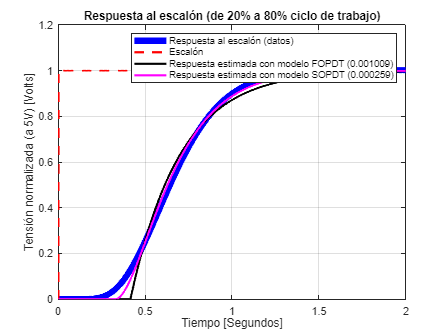

legend('Respuesta al escalón (datos)', 'Escalón', sprintf('Respuesta estimada con modelo FOPDT (%f)', error_fopdt), sprintf('Respuesta estimada con modelo SOPDT (%f)', error_sopdt));

## Modelo de las ecuaciones en diferencias

Modelo completo a partir de las ecuaciones en diferencias

Tiene un retardo porque el micro tiene un retardo cuando actúa

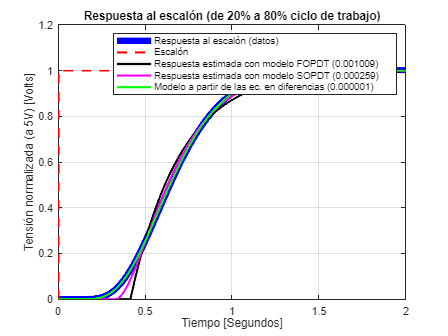

R1=10e3;
C1=10e-6;
complete_model = 1/((R1*C1*s+1)^6);
complete_model.InputDelay = 0.0753;

[ec_diff_y, ec_diff_t] = step(complete_model, step_time); ec_diff_y=reshape(ec_diff_y, size(step_resp));
plot(ec_diff_t, ec_diff_y, 'g', 'linewidth', 2);

error_ec_diff = immse(step_resp, ec_diff_y);
fprintf('El error cuadrático medio (SOPDT) entre la estimada y los datos es: %f\n', error_ec_diff);
legend('Respuesta al escalón (datos)', 'Escalón', sprintf('Respuesta estimada con modelo FOPDT (%f)', error_fopdt), sprintf('Respuesta estimada con modelo SOPDT (%f)', error_sopdt));

## Modelo de alto orden con System Identification

high_order_model = 1.261e06/(s^6 + 75.11* s^5 + 1869* s^4 + 2.523e04* s^3 + 1.888e05* s^2 + 7.568e05* s + 1.26e06);

[high_y, high_t] = step(high_order_model, step_time); high_y=reshape(high_y, size(step_resp));
close all;
plot(step_time, step_resp, 'b', 'linewidth', 2);
hold on;
grid on;
plot(step_time, step_input, '--r', 'linewidth', 2);
plot(high_t, high_y, 'g', 'linewidth', 2);

error_high = immse(step_resp, high_y);
fprintf('El error cuadrático medio (alto orden) entre lo estimado y los datos es: %f\n', error_high);

El error cuadrático medio (alto orden) entre lo estimado y los datos es: 0.003522


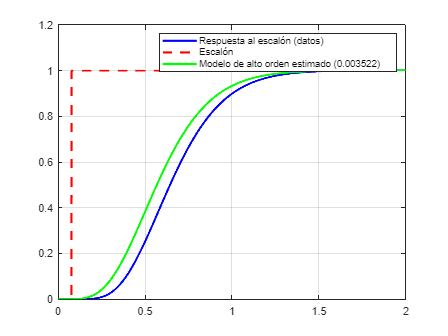

legend('Respuesta al escalón (datos)', 'Escalón', sprintf('Modelo de alto orden estimado (%f)', error_high));

## Señal PRBS

data_prbs = open('prot_sim_data_prbs.dat');

## Extraigo los datos de la simulación

El ensaño se hace un 7 bits y considerando un tiempo de rising de 2 segundos. Por lo que el ensayo debería durar TEST_DURATION segundos

IMPORTANTE ARREGLAR LA FRECUENCIA DE MUESTREO, tiene que se como 10 veces más grande

BITS=7;
SAMPLING_TIME=1.4/BITS

SAMPLING_TIME = 0.2000

TEST_DURATION=(2^BITS-1)*SAMPLING_TIME

TEST_DURATION = 25.4000

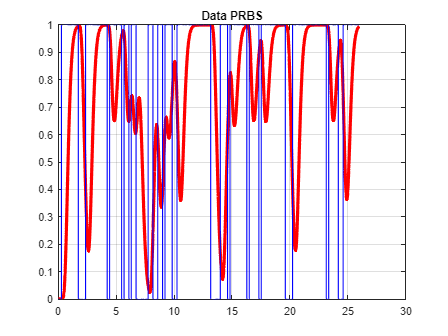

MAX_TIME=26;

DIEZMADO_POR = 1;

time_prbs = data_prbs.data(:,1);
pwm_prbs = data_prbs.data(:,2)/5;  % divido por 5 para normalizar los datos con respecto al pico de 5v
y6_prbs = data_prbs.data(:,3)/5; % divido por 5 para normalizar los datos con respecto al pico de 5v

figure();
plot(time_prbs, y6_prbs, 'r', 'linewidth', 3);
hold on;
grid on;
title('Data PRBS');
plot(time_prbs, pwm_prbs, 'b', 'linewidth', 1);

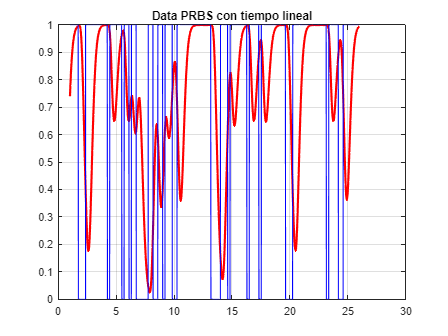

lineal_time_prbs = 1:TIME_DIFF:MAX_TIME;
lineal_pwm_prbs = interp1(time_prbs(1:DIEZMADO_POR:length(time_prbs)), pwm_prbs(1:DIEZMADO_POR:length(time_prbs)), lineal_time_prbs);
lineal_y6_prbs = interp1(time_prbs(1:DIEZMADO_POR:length(time_prbs)), y6_prbs(1:DIEZMADO_POR:length(time_prbs)), lineal_time_prbs);

figure;
plot(lineal_time_prbs, lineal_y6_prbs, 'r', 'linewidth', 2);
hold on;
grid on;
title('Data PRBS con tiempo lineal');
plot(lineal_time_prbs, lineal_pwm_prbs, 'b', 'linewidth', 1);

## Transformada de fourier de la PRBS

SEGMENTS=1500;
segment_length = floor(length(lineal_pwm_prbs)  / SEGMENTS)

segment_length = 16

tf_prbs=zeros(1, segment_length);
tf_sys=zeros(1, segment_length);
Fs = 2.5/0.2

Fs = 12.5000

freq = (-segment_length/2 : segment_length/2-1) * (Fs / segment_length);

delta_freq = Fs/SEGMENTS

delta_freq = 0.0083

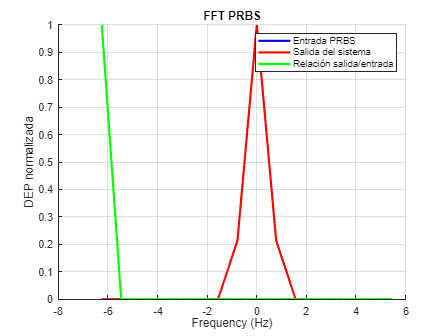


% lineal_pwm_prbs = sin(2*pi*20*lineal_time_prbs);

window = hamming(segment_length)'; % ventaneo
for m= 1:SEGMENTS
    segment_pwm = lineal_pwm_prbs((m-1)*segment_length+1 : m*segment_length);
    segment_y6 = lineal_y6_prbs((m-1)*segment_length+1 : m*segment_length);

    windowed_pwm = segment_pwm .* window;
    windowed_y6 = segment_y6 .* window;

    fft_pwm = fft(windowed_pwm);
    fft_y6 = fft(windowed_y6);

    tf_prbs = tf_prbs + fft_pwm;
    tf_sys = tf_sys + fft_y6;
end

tf_prbs = tf_prbs / SEGMENTS;
tf_sys = tf_sys / SEGMENTS;

tf_prbs_dep = abs(tf_prbs).^2;
tf_sys_dep = abs(tf_sys).^2;

tf_prbs_dep = fftshift(tf_prbs_dep);
tf_sys_dep = fftshift(tf_sys_dep);

syst_out_dep=(tf_sys_dep)./(tf_prbs_dep);
figure;
hold on;
grid on;
title('FFT PRBS');
semilogx(freq, tf_prbs_dep/max(tf_prbs_dep), 'b', 'linewidth', 2);
semilogx(freq,tf_sys_dep/max(tf_sys_dep), 'r', 'linewidth', 2);
semilogx(freq, syst_out_dep/max(syst_out_dep), 'g', 'linewidth', 2);
legend('Entrada PRBS', 'Salida del sistema', 'Relación salida/entrada');
xlabel('Frequency (Hz)');
ylabel('DEP normalizada');